# Sample 11-6

## 画像ノイズ除去

近接勾配法

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image denoising

Proximal gradient

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## 問題設定

(Problem settings)

    
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\lambda\|\mathbf{s}\|_1$$


- 
$$\mathbf{D} = \left(\begin{array}{cc} \frac{2}{3} & \frac{1}{3}\end{array}\right)\colon\quad \mathbb{R}^2\rightarrow\mathbb{R}^1$$


- 
$$\mathbf{v}=\frac{1}{2}\in\mathbb{R}^1$$


- 
$$\lambda\in[0,\infty)$$


- 
$$\mathbf{s}\in\mathbb{R}^2$$


D = [2 1]/3;
v = 0.5;

### 関数プロット

(Function plot)

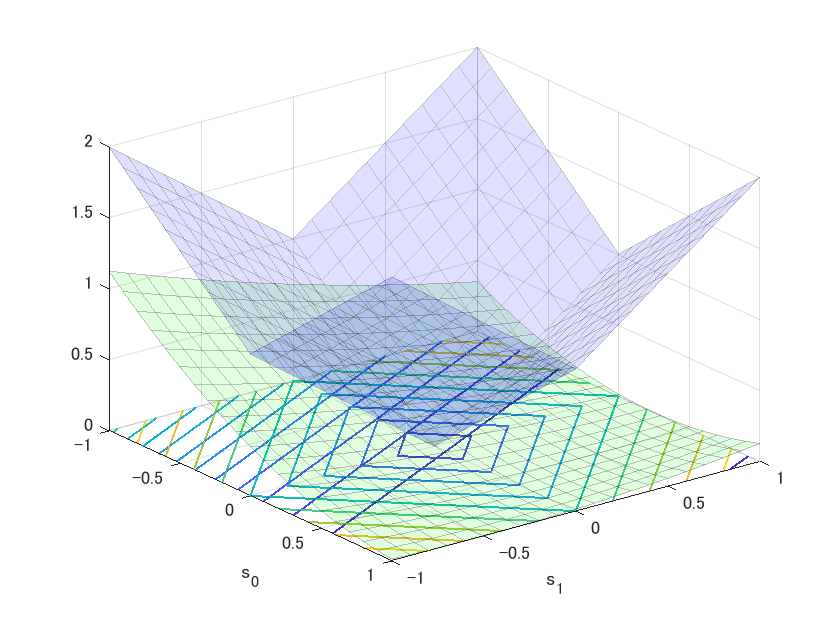

% Function settings
f = @(s0,s1) 0.5*(v-(D(1)*s0+D(2)*s1)).^2;
g = @(s0,s1) (abs(s0)+abs(s1));
% Variable settings
s0 = linspace(-1,1,21);
s1 = linspace(-1,1,21);
[S0,S1] = ndgrid(s0,s1);
F = f(S0,S1);
G = g(S0,S1);
% Surfc plot of the fidelity
figure(1)
hf = surfc(s0,s1,F);
hf(1).FaceAlpha = 0.125;
hf(1).FaceColor = 'green';
hf(1).EdgeAlpha = 0.25;
hf(2).LineWidth = 1;
set(gca,'YDir','reverse');
hold on
% Surfc plot of the regularizer
hg = surfc(s0,s1,G);
hg(1).FaceAlpha = 0.125;
hg(1).FaceColor = 'blue';
hg(1).EdgeAlpha = 0.25;
hg(2).LineWidth = 1;
xlabel('s_1')
ylabel('s_0')
hold off

### パラメータ設定

(Parameter settings)

lambda = 0.2;
gamma = 0.4;
niters = 20;

## $\ell_1$ -ノルム正則化最小自乗法による近似

($\ell_1$ -norm-regularized least square method)

         
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\lambda\|\mathbf{s}\|_1$$


近接勾配法に帰着させる．(Reduced to a proximal gradient method)

         
$$\hat{\mathbf{x}}=\arg\min_{\mathbf{x} \in V} f(\mathbf{x})+g(\mathbf{x})$$


- $f(\cdot),g(\cdot)\in\Gamma_0(\mathbb{R}^L)$: Convex functions

- $f(\cdot)$ is differentiable ( $\beta$-Lipschitz continuous)

- $\Gamma_0(\mathbb{R}^L)$ : Set of proper semi-lower-continuous convex functions

【Example】

- 
$$f(\mathbf{s})=\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2$$


- 
$$g(\mathbf{s})=\lambda\|\mathbf{s}\|_1$$


関数プロット (Function plot)

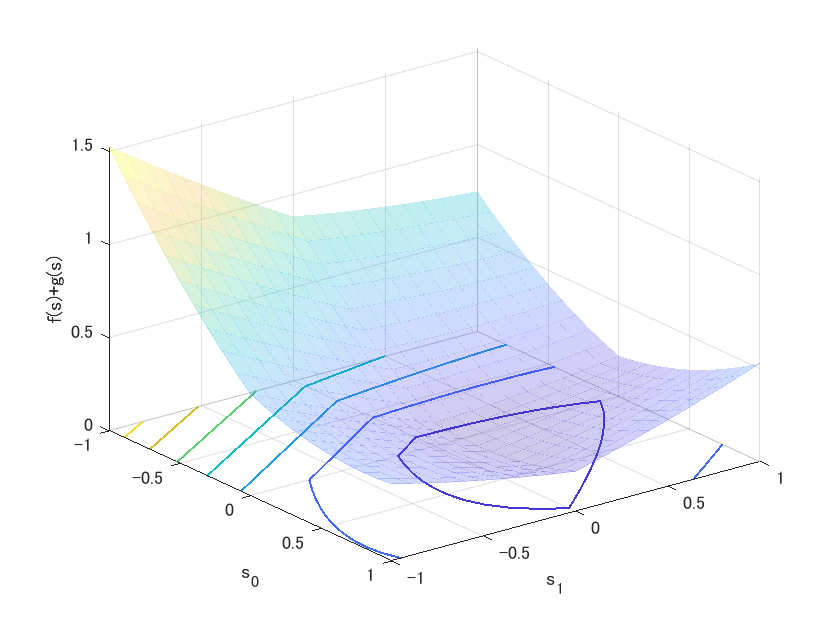

% Function setting
fg = @(s0,s1) 0.5*(v-(D(1)*s0+D(2)*s1)).^2 + lambda*(abs(s0)+abs(s1));
% Surfc plot of cost function f+g
figure(2)
J = fg(S0,S1);
hf = surfc(s0,s1,J);
hf(1).FaceAlpha = 0.25;
hf(1).EdgeAlpha = 0.25;
hf(1).EdgeColor = 'interp';
hf(2).LineWidth = 1;
set(gca,'YDir','reverse')
ylabel('s_0')
xlabel('s_1')
zlabel('f(s)+g(s)')
hold on

### 近接勾配法

(Proximal gradient method)

- Initialization: $\mathbf{x}^{(0)}$, $t\leftarrow 0$

- Proximal gradient descent: $\mathbf{x}^{(t+1)}\leftarrow \mathrm{prox}_{\gamma g}\left( \mathbf{x}^{(t)}-\gamma\nabla_\mathbf{x}f(\mathbf{x}^{(t)})\right)$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

【Example】

- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}^T(\mathbf{Ds}-\mathbf{v})$$


- 
$$\mathrm{prox}_{\gamma\lambda\|\cdot\|_{1}}(\mathbf{s})=\mathcal{T}_{\gamma\lambda}(\mathbf{s})=\mathrm{sign}(\mathbf{s})\odot\max(\mathrm{abs}(\mathbf{s})-\gamma\lambda\mathbf{1},\mathbf{0})$$


ソフト閾値処理 (Soft-thresholding)

softthresh = @(x,t) sign(x).*max(abs(x)-t,0);

初期化 (Initialization)

sp = 2*rand(2,1)-1; % in [-1,1]^2

近接勾配降下 (Proximal gradient descent)

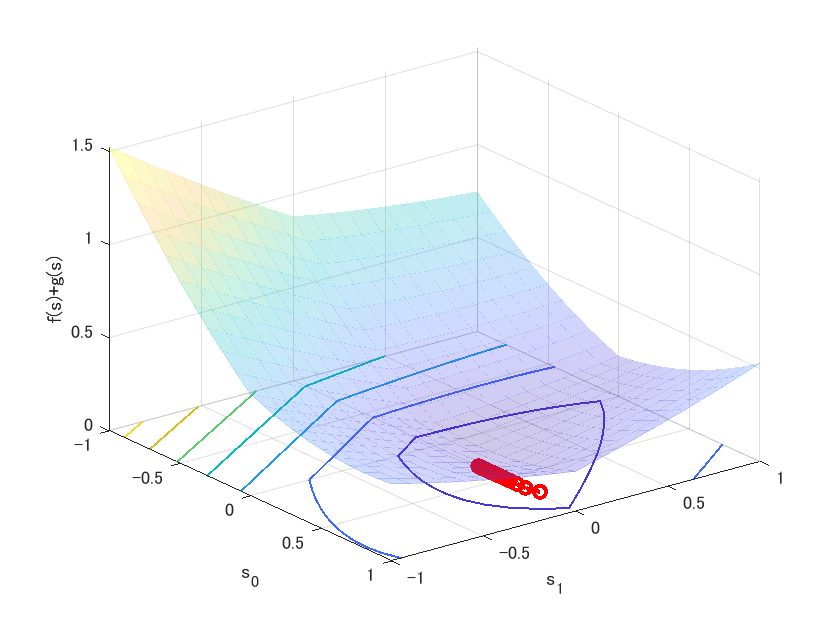

beta = D*D';
assert(gamma < 2/beta,'Step size condition is violated.')
for idx=0:niters-1
    % Preious state
    s(1,1) = sp(1); % s0
    s(2,1) = sp(2); % s1
    % Proximal gradient descent
    sc = softthresh(sp-gamma*D'*(D*sp-v),gamma*lambda);
    % sc = sign(c).*max(abs(c)-gamma*lambda,0);
    % Current state
    s(1,2) = sc(1); % s0
    s(2,2) = sc(2); % s1
    % Quiver plot
    xp = s(2,1);
    yp = s(1,1);
    xn = s(2,2);
    yn = s(1,2);
    hp = quiver(xp,yp,xn-xp,yn-yp);
    hp.Marker = 'o';
    hp.ShowArrowHead = 'on';
    hp.MaxHeadSize = 120;
    hp.MarkerSize = 6;
    hp.MarkerEdgeColor = 'r';
    hp.Color = 'r';
    hp.LineWidth = 2;
    % Update
    sp = sc;
end
hold off

### パラメータ設定

(Parameter settings)

- sgm: ノイズ標準偏差 $\sigma_w$ (Standard deviation of noise)

- nlevels: ウェーブレット段数 (Wavelet levels)

% Parameter settings
isaprxleft = true;
lambda = 10^-0.8

lambda = 0.1585

gamma = 10^-0.1

gamma = 0.7943

sgmuint8 = 20; 
sgm = sgmuint8/255;
nlevels = 3; 
niters = 80;

## 画像の読込

(Read image)

u = rgb2gray(im2double(imread('./data/lena.png')));

## 観測画像

(Observation image)

- 
$$\mathbf{v}=\mathbf{u}+\mathbf{w}$$


- 
$$\mathbf{u}=\mathbf{Ds}$$


- 
$$\mathbf{s}\sim\mathrm{Lap}\left(\mathbf{s}|\mathbf{\mu}=\mathbf{0},b\right)$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


v = imnoise(u,'gaussian',0,sgm^2);

### 非間引きハールDWT

(Undecimated Haar DWT)

import msip.udhaarwtdec2
import msip.udhaarwtrec2

#### 完全再構成の確認 (Checki the perfect reconstruction)

非間引きハールDWTはパーセバルタイト性 (The undecimated DWT satisfies the Parseval tight property,)

        
$$\mathbf{DD}^T=\mathbf{I}$$


を満たすため， $\mathbf{D}$ の転置システムは完全再構成分析システムとなり得る．(and thus Its transposition system can be a PR analysis system.)

[coefs,scales] = udhaarwtdec2(u,nlevels);
r = udhaarwtrec2(coefs,scales);
assert(norm(u-r,"fro")^2/numel(u)<1e-18,'Perfect reconstruction is violated.')

合成辞書と転置辞書の定義 (Definition of synthesis dictionary  and its adjoint)

% Definiton of dictionay and its adjoint
adjdic = @(x) udhaarwtdec2(x,nlevels); % D
syndic = @(x) udhaarwtrec2(x,scales);  % D.'

### 近接勾配法

(Proximal gradient method)

初期化 (Initialization)

sp = coefs;

近接勾配降下 (Proximal gradient descent)

if isaprxleft
    mask = ones(size(coefs));
    mask(1:prod(scales(1,:))) = 0;
    lambda = lambda * mask;
end
for idx=0:niters-1
    % Proximal gradient descent
    sc = softthresh(sp-gamma*adjdic(syndic(sp)-v),gamma*lambda);
    % Update
    sp = sc;
end

### ノイズ除去画像

(Denoised image)

r = syndic(sc);

### 画像表示

(Image show)

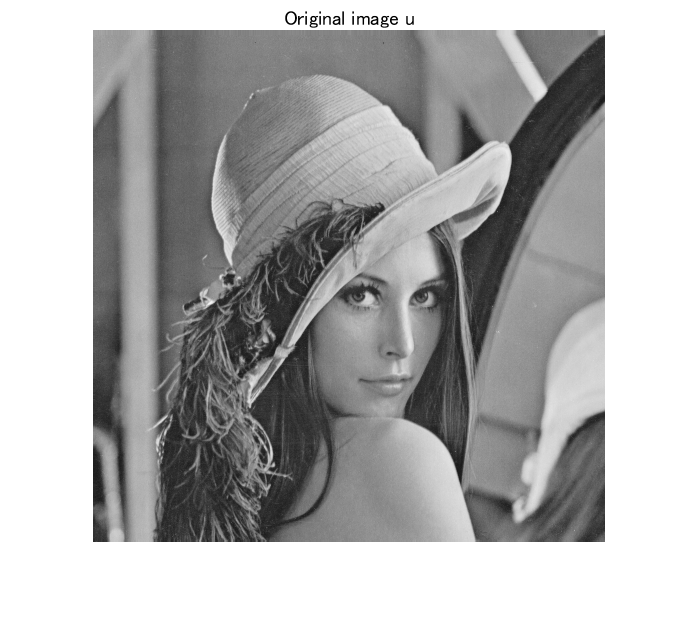

figure(1)
imshow(u);
title('Original image u')

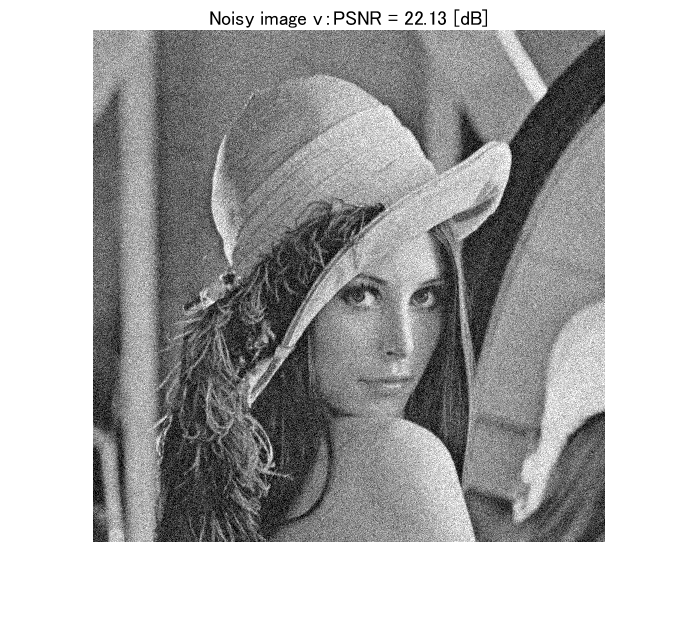

figure(2)
imshow(v)
title(sprintf('Noisy image v：PSNR = %5.2f [dB]',psnr(u,v)))

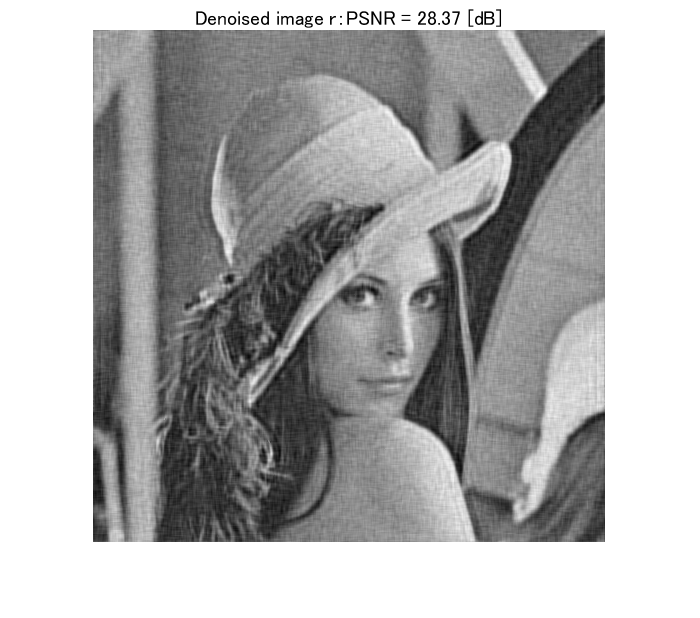

figure(3)
imshow(r)
title(sprintf('Denoised image r：PSNR = %5.2f [dB]',psnr(u,r)))

### ウェーブレット画像ノイズ除去関数

(Wavelet image denoising function)

参考資料 (Reference)

iswtb = license('checkout','wavelet_toolbox');
if iswtb
    help wdenoise2
end

wdenoise2 - Wavelet image denoising

    This MATLAB function denoises the grayscale or RGB image IM using an empirical
    Bayesian method.

    IMDEN = wdenoise2(IM)
    IMDEN = wdenoise2(IM,LEVEL)
    [IMDEN,DENOISEDCFS] = wdenoise2(___)
    [IMDEN,DENOISEDCFS,ORIGCFS] = wdenoise2(___)
    [IMDEN,DENOISEDCFS,ORIGCFS,S] = wdenoise2(___)
    [IMDEN,DENOISEDCFS,ORIGCFS,S,SHIFTS] = wdenoise2(___)
    [___] = wdenoise2(___,Name,Value)
    wdenoise2(___)

    参考 <a href="https://www.mathworks.com/help/releases/R2020a/wavelet/ref/wavedec2.html">wavedec2</a>, <a href="https://www.mathworks.com/help/releases/R2020a/wavelet/ref/wdenoise.html">wdenoise</a>

    wdenoise2 のドキュメンテーション



© Copyright, Shogo MURAMATSU, All rights reserved.